% Cargar los datos del archivo
fileID = fopen('Datos_montecarlo.txt', 'r'); 

% Inicializar un arreglo para almacenar los valores de V(n005)
V = [];

% Leer el archivo línea por línea
tline = fgetl(fileID);
while ischar(tline)
    % Verificar si la línea contiene un valor de V(n005) (con formato numérico)
    if ~isempty(regexp(tline, '^[+-]?\d*\.?\d+', 'once'))
        % Extraer el valor de V(n005) de la línea
        values = sscanf(tline, '%e');
        V = [V; values(2)];  % Solo tomar el segundo valor (V(n005))
    end
    tline = fgetl(fileID);
end

% Cerrar el archivo
fclose(fileID);

% Verificar los primeros valores extraídos
disp('Primeros 10 valores de Vout:');

Primeros 10 valores de Vout:


disp(V(1:10));

    1.0016
    1.0016
    1.0016
    0.9843
    0.9843
    0.9843
    1.0009
    1.0009
    1.0009
    0.9948



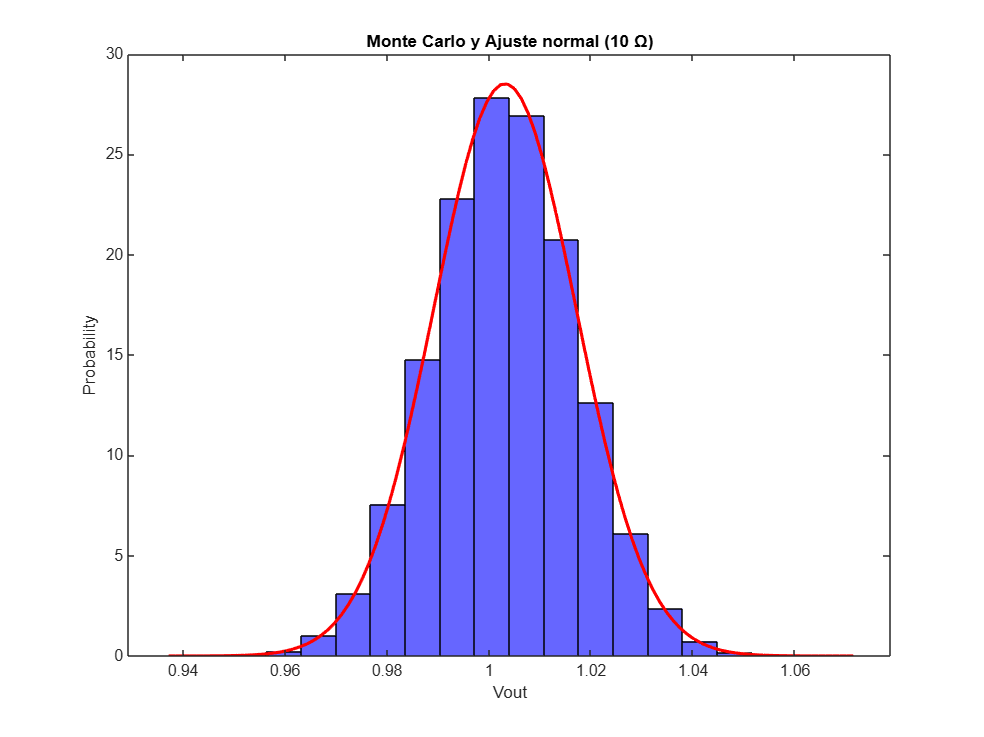


% Simulación de Monte Carlo
num_simulations = 1000;  % Número de simulaciones
simulated_values = zeros(num_simulations, length(V));

% Realizar las simulaciones con variabilidad aleatoria
for i = 1:num_simulations
    % Agregar ruido aleatorio a los valores de V
    noise = 0.01 * randn(size(V));  % Generar ruido aleatorio
    simulated_values(i, :) = V + noise;  % Simular con ruido añadido
end

% Graficar el histograma de la distribución de los valores simulados
figure;
histogram(simulated_values(:), 20, 'Normalization', 'pdf', 'FaceColor', 'b');  % Histograma con 50 bins
hold on;

% Ajuste de una distribución normal a los datos simulados
mu = mean(simulated_values(:));  % Media de los datos simulados
sigma = std(simulated_values(:));  % Desviación estándar de los datos simulados
x = linspace(min(simulated_values(:)), max(simulated_values(:)), 100);  % Rango para la función de densidad
y = normpdf(x, mu, sigma);  % Calcular la función de densidad de probabilidad normal

% Graficar la línea roja
plot(x, y, 'r', 'LineWidth', 2);  % Línea roja para la PDF ajustada

xlabel('Vout');
ylabel('Probability');
title('Monte Carlo y Ajuste normal (10 Ω)');
hold off;

Montecarlo para resistencia de 0.01 Ω

% Cargar los datos del archivo
fileID = fopen('Datos_montecarlo0_01.txt', 'r'); 

% Inicializar un arreglo para almacenar los valores de V(n005)
V = [];

% Leer el archivo línea por línea
tline = fgetl(fileID);
while ischar(tline)
    % Verificar si la línea contiene un valor de V(n005) (con formato numérico)
    if ~isempty(regexp(tline, '^[+-]?\d*\.?\d+', 'once'))
        % Extraer el valor de V(n005) de la línea
        values = sscanf(tline, '%e');
        V = [V; values(2)];  % Solo tomar el segundo valor (V(n005))
    end
    tline = fgetl(fileID);
end

% Cerrar el archivo
fclose(fileID);

% Verificar los primeros valores extraídos
disp('Primeros 10 valores de Vout:');

Primeros 10 valores de Vout:


disp(V(1:10));

    1.0016
    1.0016
    1.0016
    0.9843
    0.9843
    0.9843
    1.0009
    1.0009
    1.0009
    0.9948



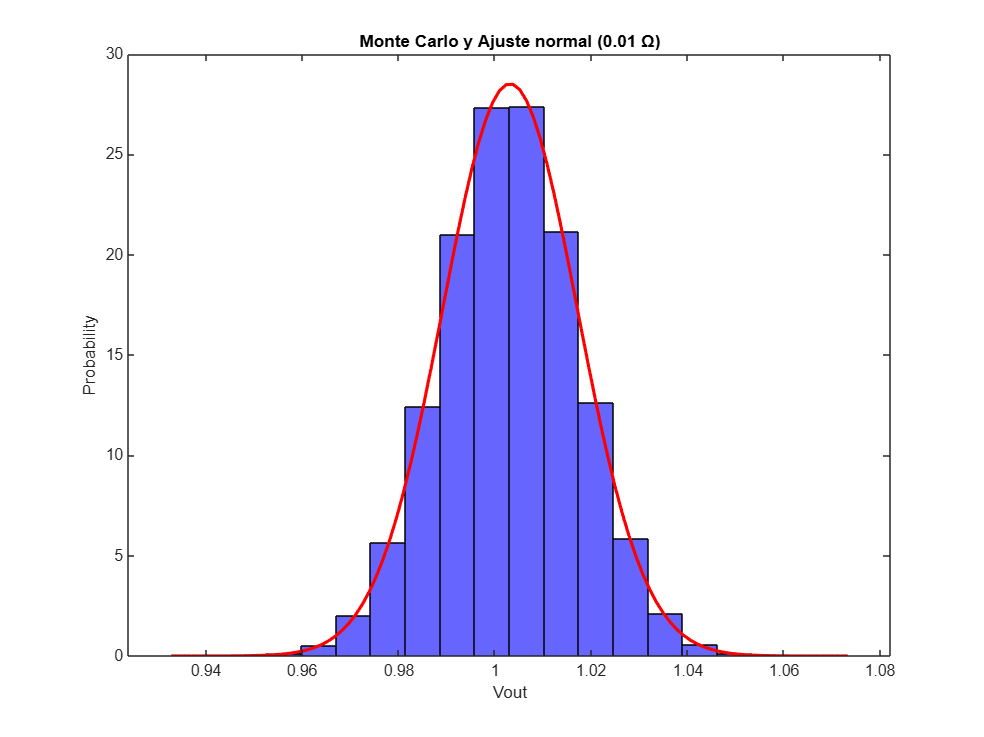


% Simulación de Monte Carlo
num_simulations = 1000;  % Número de simulaciones
simulated_values = zeros(num_simulations, length(V));

% Realizar las simulaciones con variabilidad aleatoria
for i = 1:num_simulations
    % Agregar ruido aleatorio a los valores de V
    noise = 0.01 * randn(size(V));  % Generar ruido aleatorio
    simulated_values(i, :) = V + noise;  % Simular con ruido añadido
end

% Graficar el histograma de la distribución de los valores simulados
figure;
histogram(simulated_values(:), 20, 'Normalization', 'pdf', 'FaceColor', 'b');  % Histograma con 50 bins
hold on;

% Ajuste de una distribución normal a los datos simulados
mu = mean(simulated_values(:));  % Media de los datos simulados
sigma = std(simulated_values(:));  % Desviación estándar de los datos simulados
x = linspace(min(simulated_values(:)), max(simulated_values(:)), 100);  % Rango para la función de densidad
y = normpdf(x, mu, sigma);  % Calcular la función de densidad de probabilidad normal

% Graficar la línea roja
plot(x, y, 'r', 'LineWidth', 2);  % Línea roja para la PDF ajustada

xlabel('Vout');
ylabel('Probability');
title('Monte Carlo y Ajuste normal (0.01 Ω)');
hold off;